# Demonstrates the creation of symbolic numbers, variables, and expressions.

clear
a = sym(2/3)

$$a = \frac{2}{3}$$

b = sym('2/3')

$$b = \frac{2}{3}$$

isequal(a, b)

ans = logical
   1


sym(pi)

$$ans = \pi$$

x = sym('y')

$$x = y$$

x^2

$$ans = y^{2}$$

x = sym('c')+sym('y')

$$x = c+y$$

x^2

$$ans = {\left(c+y\right)}^{2}$$

x = sym('x')

$$x = x$$

p = x^2+2*x+3

$$p = x^{2}+2\,x+3$$

q = diff(p)

$$q = 2\,x+2$$

# Demonstrates the creation of some symbolic expressions.

clear
syms theta
f = 8*cos(theta)/sin((3*theta)/(theta+1))

$$f = \frac{8\,\cos\left(\theta \right)}{\sin\left(\frac{3\,\theta }{\theta +1}\right)}$$

syms a b c x
g = a*x^3+b*x+c

$$g = a\,x^{3}+b\,x+c$$

h = diff(sqrt(5*x^2+3*x+7))

$$h = \frac{10\,x+3}{2\,\sqrt{5\,x^{2}+3\,x+7}}$$

syms t
M = [5*sin(t), -cos(t^2); cos(2*t), -sin(t)]

$$M = \left(\begin{array}{cc} 5\,\sin\left(t\right) & -\cos\left(t^{2}\right)\\ \cos\left(2\,t\right) & -\sin\left(t\right) \end{array}\right)$$

class(M)

ans = 'sym'

size(M)

ans =      2     2


det(M)

$$ans = \cos\left(2\,t\right)\,\cos\left(t^{2}\right)-5\,{\sin\left(t\right)}^{2}$$

# Demonstrates the creation of symbolic functions.

clear
syms x y
f(x,y) = x^3*y^2

$$f(x, y) = x^{3}\,y^{2}$$

class(f)

ans = 'symfun'

f(2,3)

$$ans = 72$$

clear
syms f(x,y)
f(x,y) = x^3*y^2

$$f(x, y) = x^{3}\,y^{2}$$

diff(f)

$$ans(x, y) = 3\,x^{2}\,y^{2}$$

diff(f,y)

$$ans(x, y) = 2\,x^{3}\,y$$

syms a b
g = f(a+1,b+1)/(a+b)

$$g = \frac{{\left(a+1\right)}^{3}\,{\left(b+1\right)}^{2}}{a+b}$$

h = f + x^2 + y
f(x,y) = sin(x*y)
f = sin(x*y)
class(f)

# Demonstrates the use of some simplification functions.

clear
syms x y a b
f = (x+a)^2*(y+b)

$$f = {\left(a+x\right)}^{2}\,\left(b+y\right)$$

g = expand(f)

$$g = a^{2}\,b+b\,x^{2}+a^{2}\,y+x^{2}\,y+2\,a\,b\,x+2\,a\,x\,y$$

h = factor(g)

$$h = \left(\begin{array}{ccc} a+x & a+x & b+y \end{array}\right)$$

prod(h)

$$ans = {\left(a+x\right)}^{2}\,\left(b+y\right)$$

collect(g)

$$ans = \left(b+y\right)\,x^{2}+\left(2\,a\,b+2\,a\,y\right)\,x+a^{2}\,b+a^{2}\,y$$

collect(g, y)

$$ans = \left(a^{2}+2\,a\,x+x^{2}\right)\,y+b\,a^{2}+2\,b\,a\,x+b\,x^{2}$$

collect(g, [a b])

$$ans = a^{2}\,b+y\,a^{2}+\left(2\,x\right)\,a\,b+\left(2\,x\,y\right)\,a+x^{2}\,b+x^{2}\,y$$

simplify(g)

$$ans = {\left(a+x\right)}^{2}\,\left(b+y\right)$$

simplify(sin(x)^2+cos(x)^2)

$$ans = 1$$

simplify((x^2+2*x+1)/(x+1))

$$ans = x+1$$

# Demonstrates the use of some simplification functions.

clear
syms x y
combine(sqrt(3)*sqrt(x))

$$ans = \sqrt{3\,x}$$

combine(sqrt(x)*sqrt(y))

$$ans = \sqrt{x}\,\sqrt{y}$$

assume(x, 'positive')
combine(sqrt(x)*sqrt(y))

$$ans = \sqrt{x\,y}$$

clear
syms x y
combine(sqrt(x)*sqrt(y))

$$ans = \sqrt{x\,y}$$

assumptions(x)

$$ans = 0<x$$

assume(x, 'clear')
combine(sqrt(x)*sqrt(y))

$$ans = \sqrt{x}\,\sqrt{y}$$

# Calculates and plots the curvature of a curve

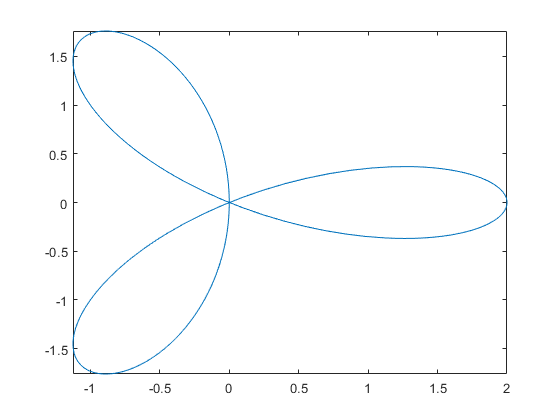

clear
syms t
x =  cos(2*t) + cos(t);
y = -sin(2*t) + sin(t);
fplot(x, [0, 2*pi]), hold on
fplot(y, [0, 2*pi]), hold off
fplot(x, y, [0,2*pi])

x1 = diff(x)

$$x1 = -2\,\sin\left(2\,t\right)-\sin\left(t\right)$$

x2 = diff(x1)

$$x2 = -4\,\cos\left(2\,t\right)-\cos\left(t\right)$$

y1 = diff(y)

$$y1 = \cos\left(t\right)-2\,\cos\left(2\,t\right)$$

y2 = diff(y1)

$$y2 = 4\,\sin\left(2\,t\right)-\sin\left(t\right)$$

n = x1*y2 - y1*x2

$$n = -\left(2\,\cos\left(2\,t\right)-\cos\left(t\right)\right)\,\left(4\,\cos\left(2\,t\right)+\cos\left(t\right)\right)-\left(4\,\sin\left(2\,t\right)-\sin\left(t\right)\right)\,\left(2\,\sin\left(2\,t\right)+\sin\left(t\right)\right)$$

d = (x1^2 + y1^2)^(3/2)

$$d = {\left({\left(2\,\sin\left(2\,t\right)+\sin\left(t\right)\right)}^{2}+{\left(2\,\cos\left(2\,t\right)-\cos\left(t\right)\right)}^{2}\right)}^{3/2}$$

n = simplify(n)

$$n = 2\,\cos\left(3\,t\right)-7$$

d = simplify(d)

$$d = {\left(5-4\,\cos\left(3\,t\right)\right)}^{3/2}$$

k = n / d

$$k = \frac{2\,\cos\left(3\,t\right)-7}{{\left(5-4\,\cos\left(3\,t\right)\right)}^{3/2}}$$

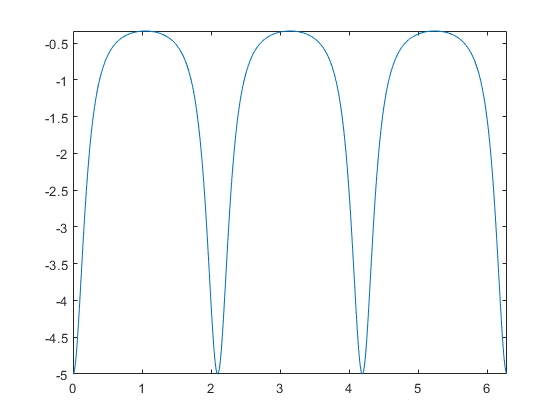

fplot(k, [0, 2*pi])

k = subs(k, cos(3*t), 'C')

$$k = \frac{2\,C-7}{{\left(5-4\,C\right)}^{3/2}}$$

# Plots the p.d.f. and c.d.f. curves of the standard normal distribution.

clear
mu = 0; sigma = 1;
syms x
f = exp(-(x-mu)^2/(2*sigma^2))/(sqrt(2*pi)*sigma);
fplot(f, [-3, 3]), hold on
p = int(f, x, -inf, x);
fplot(p, [-3, 3])
axis([-3, 3, 0, 1])
xlabel('x')
title('Standard Normal Distribution')
legend('Probability Density Function', ...
       'Cumulative Distribution Function', ...
       'Location', 'northwest')

# Demonstrates the use of the function limit.

clear
syms x h n
f(x) = sin(x);
g(x) = limit((f(x+h)-f(x))/h, h, 0)

$$g(x) = \cos\left(x\right)$$

g(x) = diff(f)
f(x) = x^n;
g(x) = limit((f(x+h)-f(x))/h, h, 0)
g(x) = diff(f)
limit(sin(x)/x, x, 0)
f(x) = limit((1+x/n)^n, n, inf)
vpa(f(1))

# Demonstrates the use of the function taylor.

clear
syms x
f(x) = sin(x);
T1(x) = taylor(f)

$$T1(x) = \frac{x^{5}}{120}-\frac{x^{3}}{6}+x$$

T2(x) = taylor(f, x, 'Order', 8)

$$T2(x) = -\frac{x^{7}}{5040}+\frac{x^{5}}{120}-\frac{x^{3}}{6}+x$$

T3(x) = taylor(f, x, pi/4)

$$T3(x) = \frac{\sqrt{2}\,\left(x-\frac{\pi }{4}\right)}{2}+\frac{\sqrt{2}}{2}-\frac{\sqrt{2}\,{\left(x-\frac{\pi }{4}\right)}^{2}}{4}-\frac{\sqrt{2}\,{\left(x-\frac{\pi }{4}\right)}^{3}}{12}+\frac{\sqrt{2}\,{\left(x-\frac{\pi }{4}\right)}^{4}}{48}+\frac{\sqrt{2}\,{\left(x-\frac{\pi }{4}\right)}^{5}}{240}$$

vpa(f(pi/4))

$$ans = 0.70710678118654752440084436210485$$

vpa(T1(pi/4))

$$ans = 0.70714304577936024806870707375421$$

vpa(T2(pi/4))

$$ans = 0.70710646957517807081792046856723$$

vpa(T3(pi/4))

$$ans = 0.70710678118654752440084436210485$$

# Demonstrates the symbolic solution of algebraic equations.

clear
syms x a b c
eq = a*x^2+b*x+c;
solve(eq)

$$ans = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

eq = (cos(x)==1);
solve(eq)

$$ans = 0$$

[sol, param, cond] = solve(eq, 'ReturnConditions', true)

$$sol = 2\,\pi \,k$$

$$param = k$$

$$cond = k\in \mathbb{Z}$$

syms y d e f
eq1 = a*x+b*y==c;
eq2 = d*x+e*y==f;
sol = solve(eq1, eq2)
[sol.x, sol.y]
[A, b] = equationsToMatrix(eq1, eq2, x, y)
sol = linsolve(A, b)
sol = A\b
sol = inv(A)*b

# Hooke’s Law

clear
syms E v G
K = [1/E, -v/E, -v/E,   0,   0    0;
    -v/E,  1/E, -v/E,   0,   0,   0;
    -v/E, -v/E,  1/E,   0,   0,   0;
       0,    0,    0, 1/G,   0,   0;
       0,    0,    0,   0, 1/G,   0;
       0,    0,    0,   0,   0, 1/G]

$$K = \left(\begin{array}{cccccc} \frac{1}{\text{E}} & -\frac{v}{\text{E}} & -\frac{v}{\text{E}} & 0 & 0 & 0\\ -\frac{v}{\text{E}} & \frac{1}{\text{E}} & -\frac{v}{\text{E}} & 0 & 0 & 0\\ -\frac{v}{\text{E}} & -\frac{v}{\text{E}} & \frac{1}{\text{E}} & 0 & 0 & 0\\ 0 & 0 & 0 & \frac{1}{G} & 0 & 0\\ 0 & 0 & 0 & 0 & \frac{1}{G} & 0\\ 0 & 0 & 0 & 0 & 0 & \frac{1}{G} \end{array}\right)$$

F = inv(K)

$$F = \begin{array}{l} \left(\begin{array}{cccccc} \sigma_{2} & \sigma_{1} & \sigma_{1} & 0 & 0 & 0\\ \sigma_{1} & \sigma_{2} & \sigma_{1} & 0 & 0 & 0\\ \sigma_{1} & \sigma_{1} & \sigma_{2} & 0 & 0 & 0\\ 0 & 0 & 0 & G & 0 & 0\\ 0 & 0 & 0 & 0 & G & 0\\ 0 & 0 & 0 & 0 & 0 & G \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{\text{E}\,v}{2\,v^{2}+v-1}\\ \sigma_{2}=\frac{\text{E}\,\left(v-1\right)}{2\,v^{2}+v-1} \end{array}$$

# Obtains a general solution for a 2nd-order ODE representing an undamped free vibration but fails to obtain a particular solution.

clear
syms t m k delta omega clear
syms x(t)
x1(t) = diff(x);
x2(t) = diff(x1);
ode = m*x2+k*x==0;
x(t) = dsolve(ode)
assume([m, k], 'positive')
x(t) = dsolve(ode)
x(t) = combine(x)
x(t) = subs(x, (k/m)^(1/2), omega)
x(t) = dsolve(ode, x(0)==delta, x1(0)==0)

# Obtains a particular solution for the 2nd-order ODE by reducing it to a system of two first-order ODEs.

clear
syms t m k delta omega clear
syms x(t) v(t)
x1(t) = diff(x);
v1(t) = diff(v);
ode1 = m*v1+k*x==0;
ode2 = x1==v;
assume([m, k], 'positive')
sol = dsolve(ode1, ode2, x(0)==delta, v(0)==0)
x(t) = sol.x
v(t) = sol.v
x(t) = combine(x)
x(t) = subs(x, (k/m)^(1/2), omega)
v(t) = combine(v)
v(t) = subs(v, (k/m)^(1/2), omega)

# Obtains a particular solution for a 2nd-order ODE representing a damped free vibration.

clear
syms t x(t) v(t)
m = 1; c = 1; k = 100; delta = 0.2;
x1(t) = diff(x);
v1(t) = diff(v);
ode1 = m*v1+c*v+k*x==0;
ode2 = x1==v;
sol = dsolve(ode1, ode2, x(0)==delta, v(0)==0)

sol = struct with fields:
    x: [1×1 sym]
    v: [1×1 sym]


x(t) = sol.x

$$x(t) = \frac{\cos\left(\frac{\sqrt{399}\,t}{2}\right)}{5\,\sqrt{{\mathrm{e}}^{t}}}+\frac{\sqrt{399}\,\sin\left(\frac{\sqrt{399}\,t}{2}\right)}{1995\,\sqrt{{\mathrm{e}}^{t}}}$$

v(t) = sol.v

$$v(t) = -\frac{40\,\sqrt{399}\,\sin\left(\frac{\sqrt{399}\,t}{2}\right)}{399\,\sqrt{{\mathrm{e}}^{t}}}$$

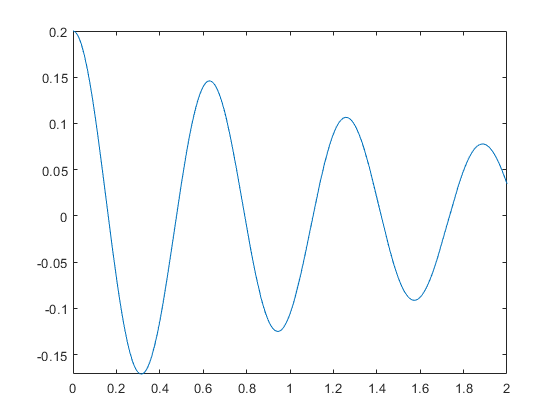

fplot(x, [0,2])

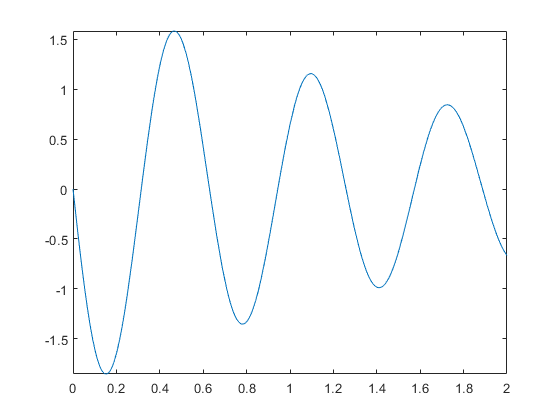

fplot(v, [0,2])

vpa(x, 5)

$$ans(t) = \frac{0.2\,\cos\left(9.9875\,t\right)}{\sqrt{{\mathrm{e}}^{t}}}+\frac{0.010013\,\sin\left(9.9875\,t\right)}{\sqrt{{\mathrm{e}}^{t}}}$$

vpa(v, 5)

$$ans(t) = -\frac{2.0025\,\sin\left(9.9875\,t\right)}{\sqrt{{\mathrm{e}}^{t}}}$$